# **Runge Kutta Orden 4**

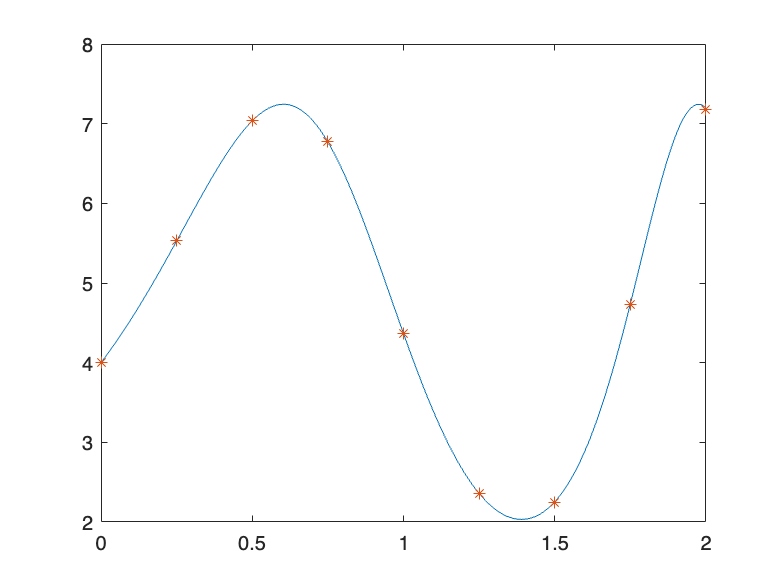

clear all

xi = 0;
yi = 4;
h = 0.25;
xf = 2;
n = (xf - xi) / h;

f = @(x,y) (y+1)*(x+1)*cos(x^2 + 2*x);

x = zeros(1, n+1);
y = zeros(1, n+1);

x(1) = xi;
y(1) = yi;
    
for i = 1:n
    x(i+1) = x(i) + h;     
    k1 = f(x(i),y(i));
    k2 = f(x(i) + h/2, y(i) + (h/2)*k1);
    k3 = f(x(i) + h/2, y(i) + k2*(h/2));
    k4 = f(x(i) + h, y(i) + h*k3);
    y(i+1) = y(i) + (h/6)*(k1 + 2*k2 + 2*k3 + k4);
end

xa = 0:0.01:2;
ya = 5.*exp(0.5*sin(xa.^2+2.*xa))-1;
plot(xa,ya,x,y,"*")